## TTT4135 MULTIMEDIA SIGNAL PROCESSING Assignment 1

close all;
clear;

## Part 1:

### a)

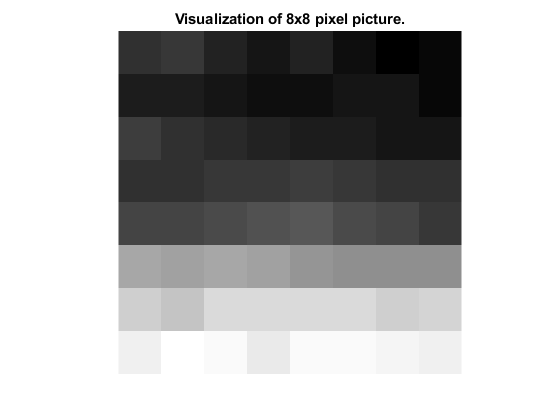

pic_mat =  [124 125 122 120 122 119 117 118
            121 121 120 119 119 120 120 118
            126 124 123 122 121 121 120 120
            124 124 125 125 126 125 124 124
            127 127 128 129 130 128 127 125
            143 142 143 142 140 139 139 139
            150 148 152 152 152 152 150 151
            156 159 158 155 158 158 157 156];
figure()
imshow(log(abs(pic_mat)),[],'InitialMagnification','fit');
title('Visualization of 8x8 pixel picture.')

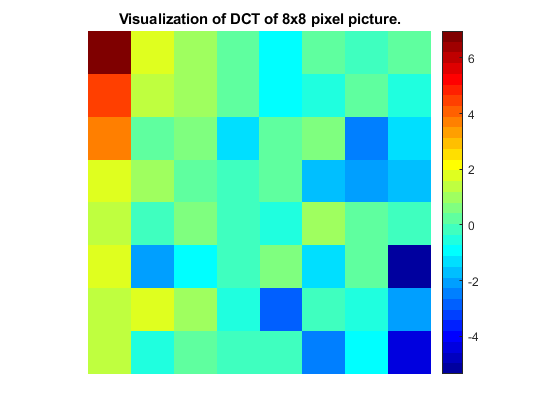

% If we want to add some color
% colormap(gca,copper(64))
% colorbar
        
dct_mat = dct2(pic_mat);

figure()
imshow(log(abs(dct_mat)),[],'InitialMagnification','fit');
title('Visualization of DCT of 8x8 pixel picture.')
colormap(gca,jet(32))
colorbar

Here we see that the highest consentrarion of frequencies in the picutre is in the low frequencies. Elsewhere we have some minor contributions to some of the higher frequency components.

### b)

quant_table =  [16 11 10 16  24  40  51  61;
                12 12 14 19  26  58  60  55;
                14 13 16 24  40  57  69  56;
                14 17 22 29  51  87  80  62;
                18 22 37 56  68 109 103  77;
                24 35 55 64  81 104 113  92;
                49 64 78 87 103 121 120 101;
                72 92 95 98 112 100 103  99];

%quant_table(2,:)
%k = zeros('like',quant_table)

k = (dct_mat./quant_table) + 0.5

k =    66.9922    1.0968    0.2758    0.5763    0.4844    0.4728    0.5156    0.5186
   -8.0366    0.8806    0.6617    0.5590    0.5138    0.4891    0.4824    0.4913
    3.1979    0.6011    0.6109    0.5108    0.4623    0.4611    0.4985    0.5042
    0.0947    0.6319    0.4397    0.4720    0.5278    0.5025    0.4983    0.5027
    0.3125    0.4661    0.4525    0.5139    0.4908    0.4756    0.4874    0.5099
    0.7496    0.4960    0.4916    0.4878    0.5247    0.4974    0.5130    0.5001
    0.5811    0.5864    0.5308    0.4936    0.4995    0.4930    0.4956    0.4987
    0.4523    0.5057    0.4887    0.5089    0.5086    0.5009    0.5032    0.5001


### c)

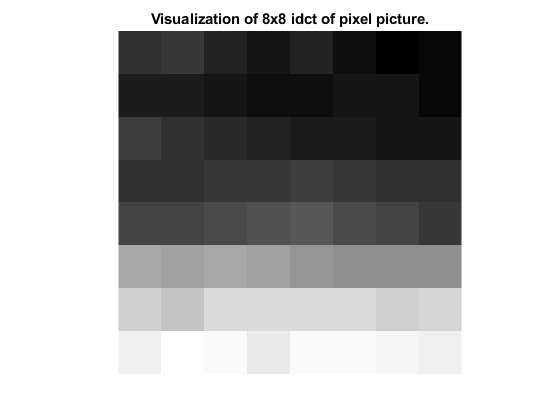

dct_mat_inv = ((k-0.5).*quant_table);
idct_pic = idct2(dct_mat_inv);

figure()
imshow(log(abs(idct_pic)),[],'InitialMagnification','fit');
title('Visualization of 8x8 idct of pixel picture.')

diff = log10(sum((pic_mat - idct_pic),'all'))*10

diff = -115.6408